# 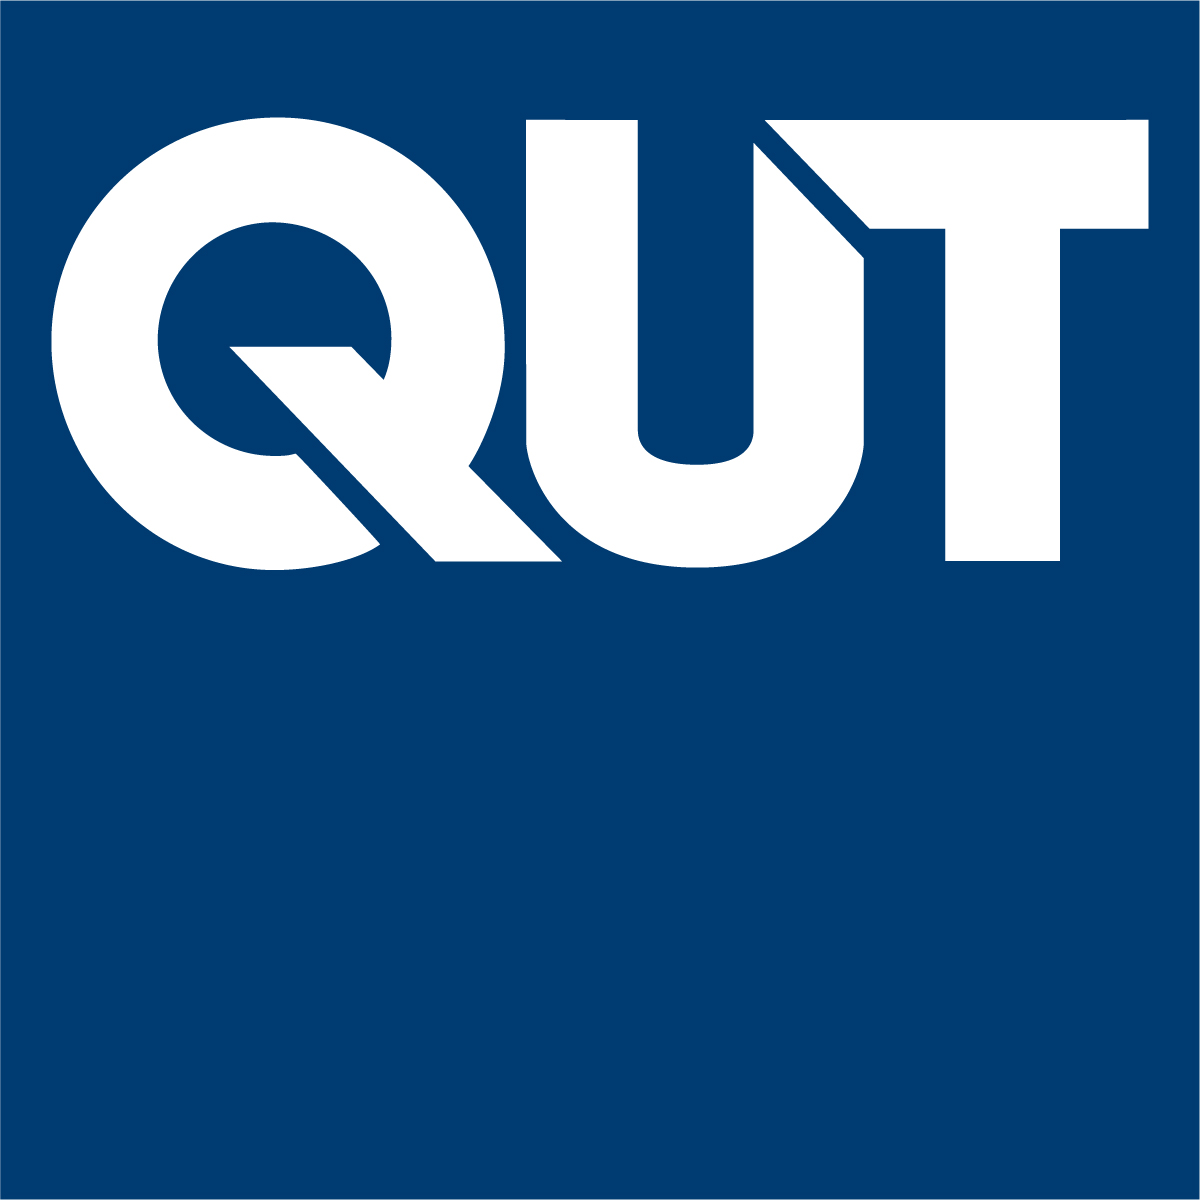

# MXB201 Linear Algebra in the Real World™  Series

Professor Tim Moroney,  2022

V1.0

## Least squares, eigenvalues and normal distributions

Linear Algebra prerequisites:

- Least squares problems

- Matrix diagonalisation

## **Disclaimer**

This worksheet has been designed to introduce concepts that will be essential in your group project: namely least squares problems for an unknown *matrix,* and applications of matrix diagonalisation, which are at the heart of Part I of that project.

Since we can't solve your group project for you, the application we have chosen to illustrate these concepts in the worksheet comes from statistics.

However, the approach taken in this worksheet is **not** the best way to solve the statistics problem.  It's *a way*, but it's not the *best* way.  The statistics problem is merely providing a familiar platform for us to cover the techniques that certainly *are* the right way to solve the problem in your group project.

With that said, on with the show!

## The multivariate normal distribution

In statistics, the normal distribution is one of the important continuous probability distributions.  For a single variable its probability density function (PDF) is given by:


$$f(x) = \frac{1}{\sqrt{2\pi}\sigma} \exp\Big({-\frac{1}{2} (x-\mu)^2/\sigma^2\Big)$$


where $\mu$ is the mean, and $\sigma^2$ is the variance.  But the world doesn't confine itself to one dimension of variability.  In $n$ dimensions, we have the generalisation of the normal distribution PDF given by


$$f(\mathbf{x}) = (2\pi)^{-\frac{n}{2}}\det(\Sigma)^{-\frac{1}{2}} \exp\left(-\frac{1}{2}(\mathbf{x}-\mathbf{\mu})^T\, \Sigma^{-1}\, (\mathbf{x}-\mathbf{\mu})\right)$$


where now $\mathbf{x} = [x_1, \ldots x_n]^T$ and  $\mathbf{\mu} = [\mu_1, \ldots \mu_n]^T$ are vectors in $\mathbb{R}^n$, and $\Sigma \in \mathbb{R}^{n \times n}$ is the *covariance matrix*, playing the analogous role to the single variable variance $\sigma^2$.  More information on the covariance matrix can be found by consulting your friendly statistics lecturer -- its statistical interpretation isn't the focus of this worksheet.

To keep things nice and visual, we will be working with data in two spatial dimensions.  The workspace `random_points` has a two-column array `R `of random points drawn from a normal distribution.

clear
load random_points
npts = size(R, 1)

npts = 1000

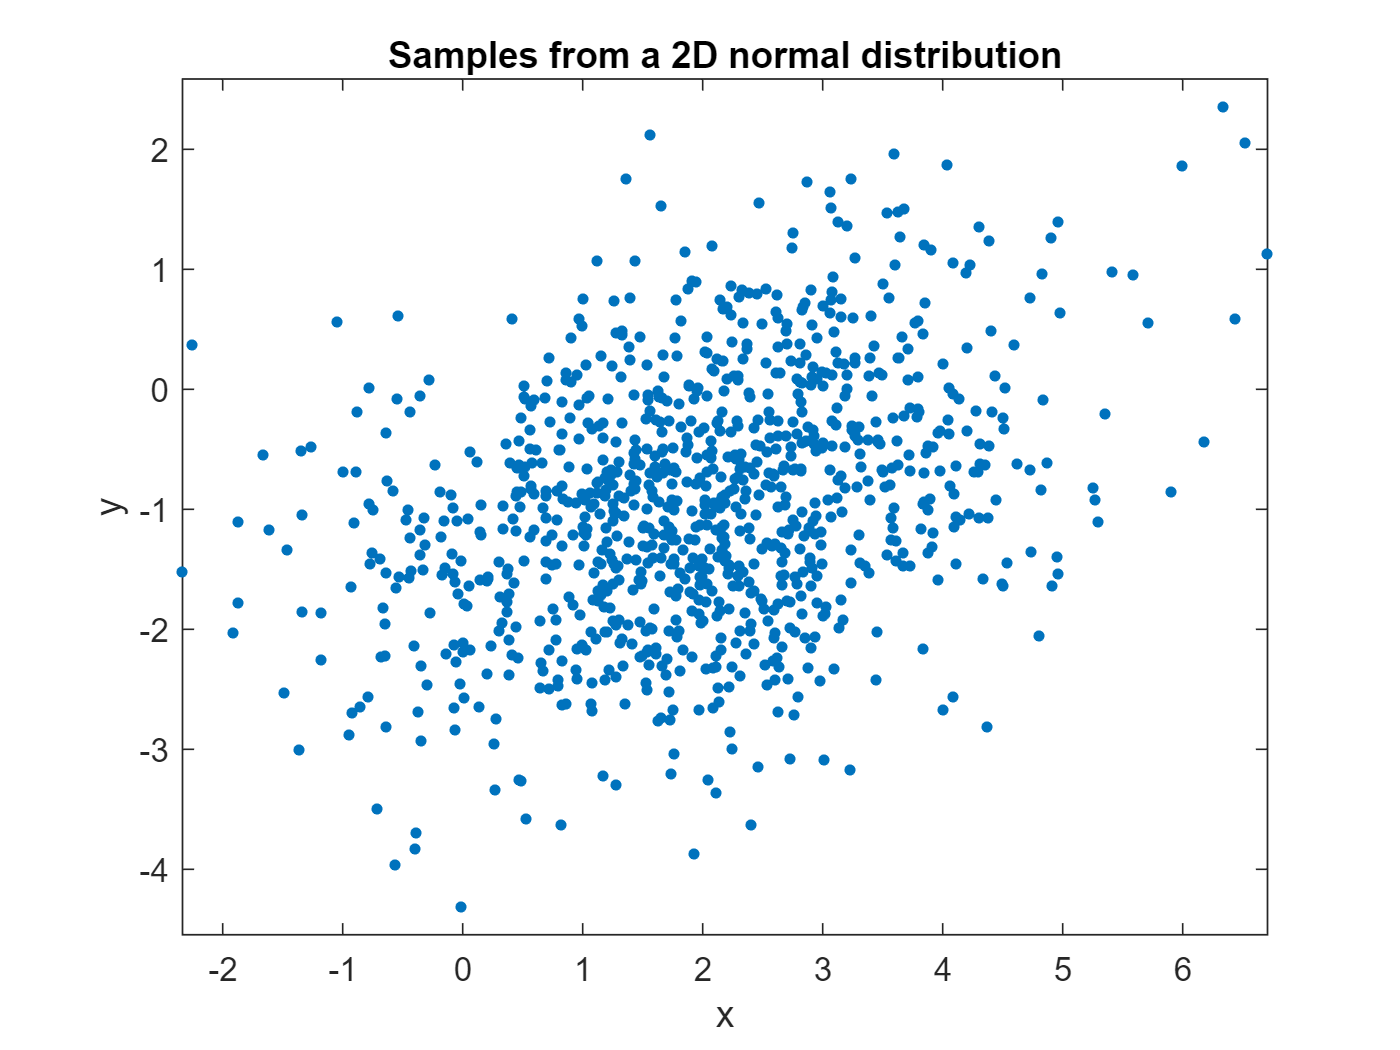

f1 = figure;
plot(R(:,1), R(:,2), '.', 'MarkerSize', 10)
xlabel x
ylabel y
title('Samples from a 2D normal distribution')
axis equal

A classical problem in statistics is to estimate the parameters of the distribution, given the data.  So that will be our little problem for this week: estimating the mean $\mathbf{\mu} = \left[\matrix{\mu_x \cr \mu_y}\right]$ and the covariance matrix $\Sigma = \left[ \matrix{\sigma_{xx} & \sigma_{xy} \cr \sigma_{xy} & \sigma_{yy}  }\right]$ given these data.

### First the easy part

Estimating the mean couldn't be easier:

mu = mean(R)

mu =     1.9812   -0.9302


So, job half done already!

Actually, now that we've got the mean taken care of, it will make our life simpler from here on if we *mean-centre* the data.  That is, subtract the mean, so the data are centred on zero.

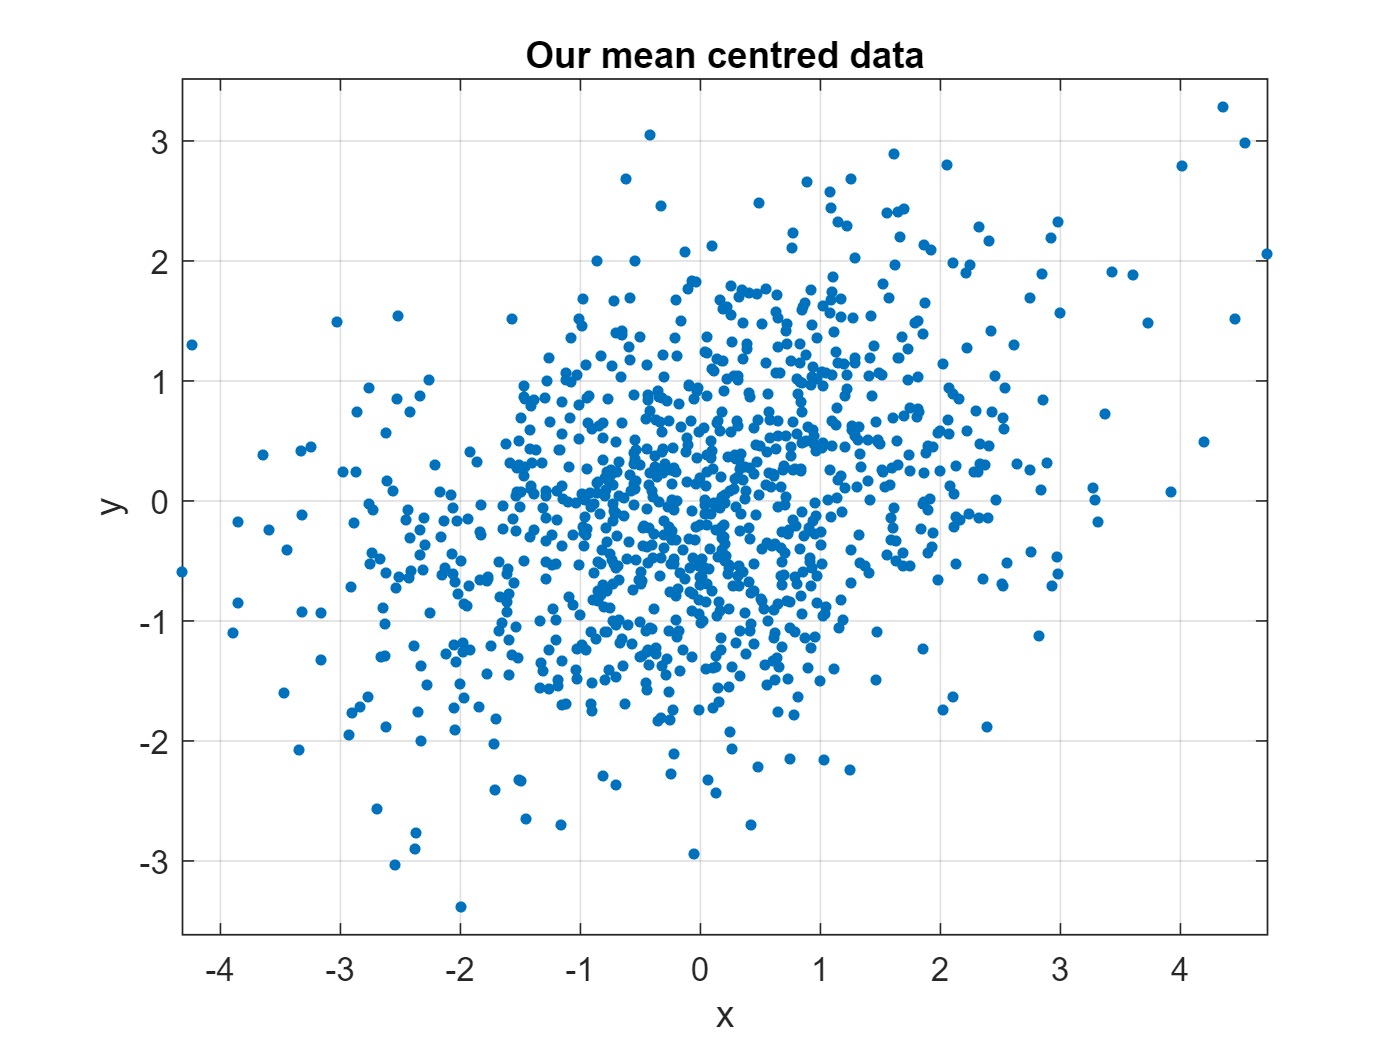

MC = R - mu;  % mean-centred data
f2 = figure;
plot(MC(:,1), MC(:,2), '.', 'MarkerSize', 10)
xlabel x
ylabel y
title('Our mean centred data')
axis equal
grid on

The mean of our new data is zero, so the PDF formula becomes simpler (also we know that $n = 2$, which also helps).


$$f(\mathbf{x}) = (2\pi)^{-1}\det(\Sigma)^{-\frac{1}{2}} \exp\left(-\frac{1}{2}\mathbf{x}^T\, \Sigma^{-1}\, \mathbf{x}\right)$$


While we're at it, it's kind of dumb having the inverse matrix $\Sigma^{-1}$ in there.  Let's just define that problem away, and set $K = \Sigma^{-1}$ (statisticians call $K$ the *precision matrix*).  Since $\Sigma$ is symmetric, so too is $K$.  So here's our PDF formula:


$$f(\mathbf{x}) = \frac{1}{2\pi}\sqrt{\det(K)} \exp\left(-\frac{1}{2}\mathbf{x}^T K \mathbf{x}\right)$$


where $K = \left[ \matrix{k_{xx} & k_{xy} \cr k_{xy} & k_{yy}  }\right]$ is the unknown *matrix* we wish to estimate from the data.

The role of the precision matrix $K$ is to stretch and squish the classical "bell curve" shape along different axes.  For our data set, it's clear that the probability density function is not rotationally symmetric: it should come out something like the diagram shown below.

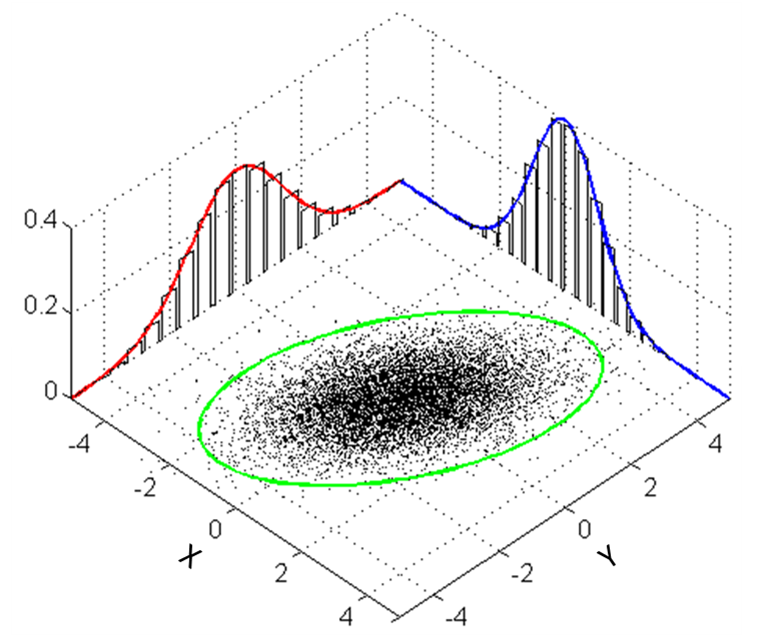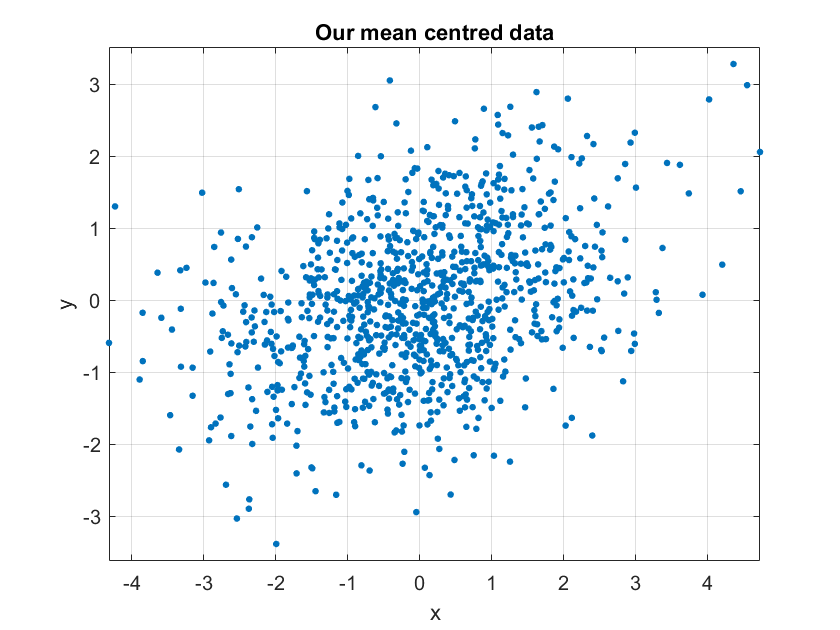

https://en.wikipedia.org/wiki/File:MultivariateNormal.png

### Histogram

In fact, we can get a very coarse sense of what our PDF looks like, by simply making a histogram of our mean centred data.

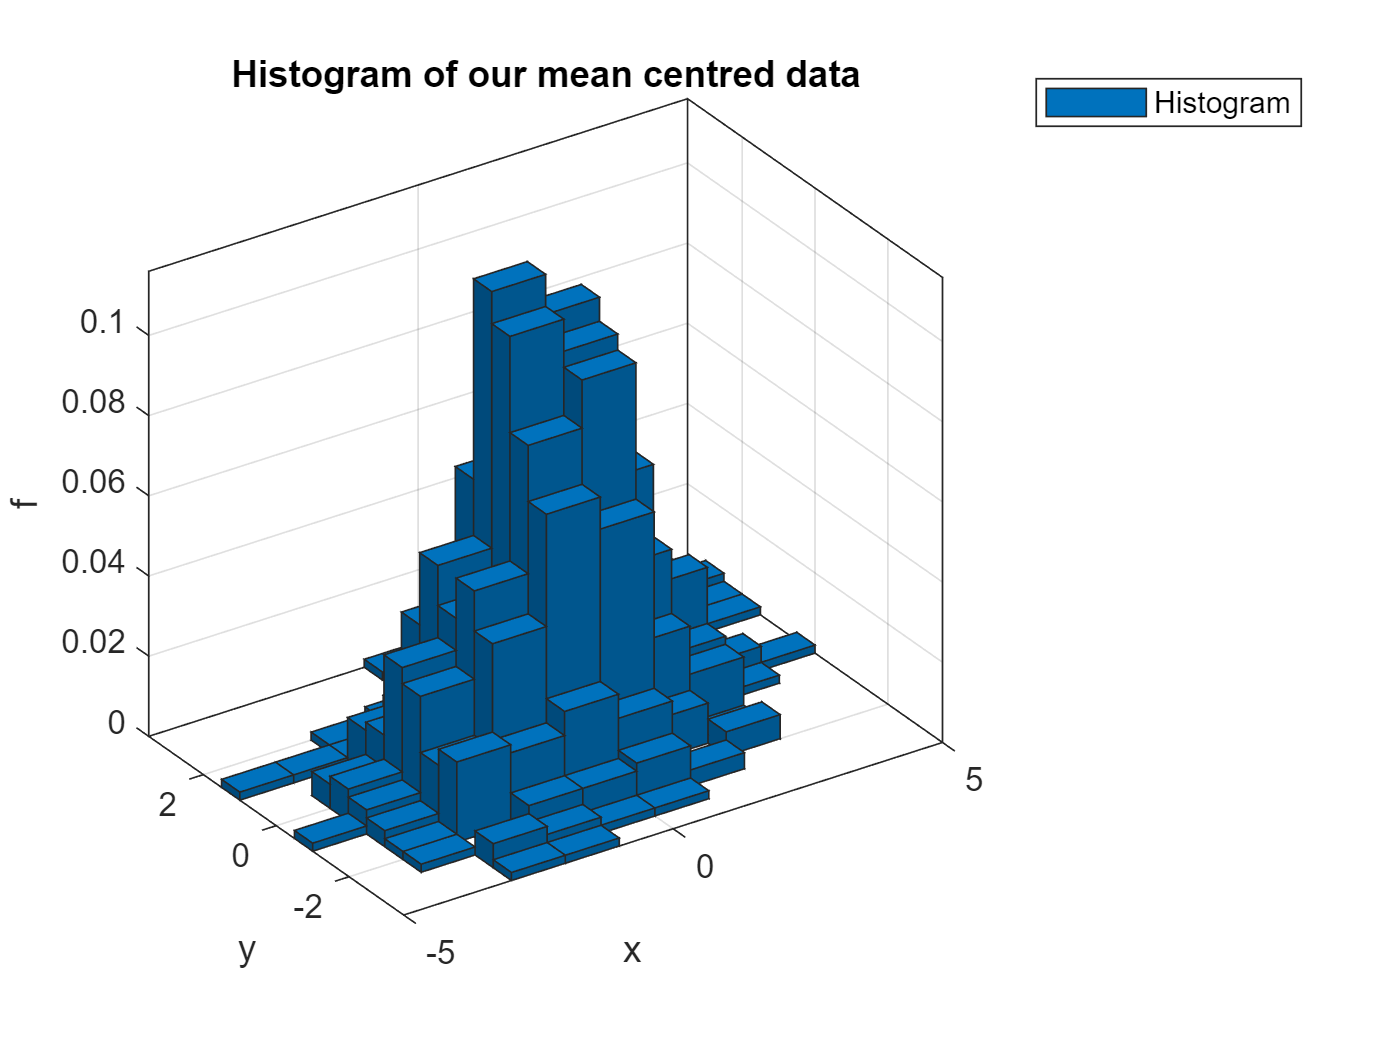

figure
h = histogram2(MC(:,1), MC(:,2), 'Normalization', 'pdf', 'DisplayName', 'Histogram');
set(gca, 'DataAspectRatio', [70, 70, 1])
xlabel x, ylabel y, zlabel f
title('Histogram of our mean centred data')
legend

We only have 1000 samples, which isn't much for a 2D histogram, so it's very blocky.  But if you pop the figure out and rotate it in 3D you should be able to get a sense of the shape of the PDF we're looking to find: the streched/squished bell-curve


$$f(\mathbf{x}) = \frac{1}{2\pi}\sqrt{\det(K)} \exp\left(-\frac{1}{2}\mathbf{x}^T K \mathbf{x}\right)$$


which would arise in the limit of the histogram if we had infinite data samples.  If you plotted the surface defined by $f$ it would look something like what you'd get if you threw a blanket over the top of that blocky tower and let it hang down around it.

To build the histogram, MATLAB has binned the data automatically for us.  These are the bin edges it chose.

xEdges = h.XBinEdges

xEdges =     -5    -4    -3    -2    -1     0     1     2     3     4     5


yEdges = h.YBinEdges

yEdges =    -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000


We can see that the bin widths are different in $x$ and $y$, which explains why the blocks are rectangular rather than square.

h.BinWidth

ans =     1.0000    0.5000


We chose to normliase the PDF when we constructed it, so the counts in each bin were scaled.

F = h.Values  % not integer counts; they have been scaled

F =          0         0         0         0         0    0.0020         0         0         0    0.0020         0         0         0         0
         0         0    0.0020    0.0020    0.0040    0.0060    0.0080    0.0060         0    0.0020         0         0         0         0
    0.0020    0.0060         0    0.0200    0.0160    0.0300    0.0340    0.0140    0.0120    0.0020    0.0020         0         0         0
    0.0020    0.0040    0.0080    0.0180    0.0420    0.0520    0.0420    0.0520    0.0340    0.0100    0.0040         0         0         0
         0    0.0020    0.0080    0.0240    0.0700    0.0840    0.1080    0.1160    0.0660    0.0340    0.0160    0.0080    0.0020    0.0020
         0    0.0020    0.0100    0.0180    0.0620    0.0960    0.1000    0.1060    0.0680    0.0700    0.0340    0.0080    0.0020         0
         0         0    0.0040         0    0.0100    0.0260    0.0420    0.0600    0.0480    0.0480    0.0260    0.0200    0.0060         0
         

The scaling is precisely so that this histogram is a true PDF: it integrates to 1.

fvec = F(:)  % histogram values as a big column

fvec =          0
         0
    0.0020
    0.0020
         0
         0
         0
         0
         0
         0


sum(fvec * prod(h.BinWidth))  % integrates (sums) to 1

ans = 1

It will be convenient to calculate the midpoints of each bin.  Here's a simple function to do the job.

midpoints = @(vec) (vec(1:end-1) + vec(2:end))/2;

Here then, are the bin midpoints in $x$ and $y$.

xMidpoints = midpoints(xEdges)

xMidpoints =    -4.5000   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000    4.5000


yMidpoints = midpoints(yEdges)

yMidpoints =    -3.2500   -2.7500   -2.2500   -1.7500   -1.2500   -0.7500   -0.2500    0.2500    0.7500    1.2500    1.7500    2.2500    2.7500    3.2500


To be sure we're on the right track, let's overlay the histogram values at the midpoints.

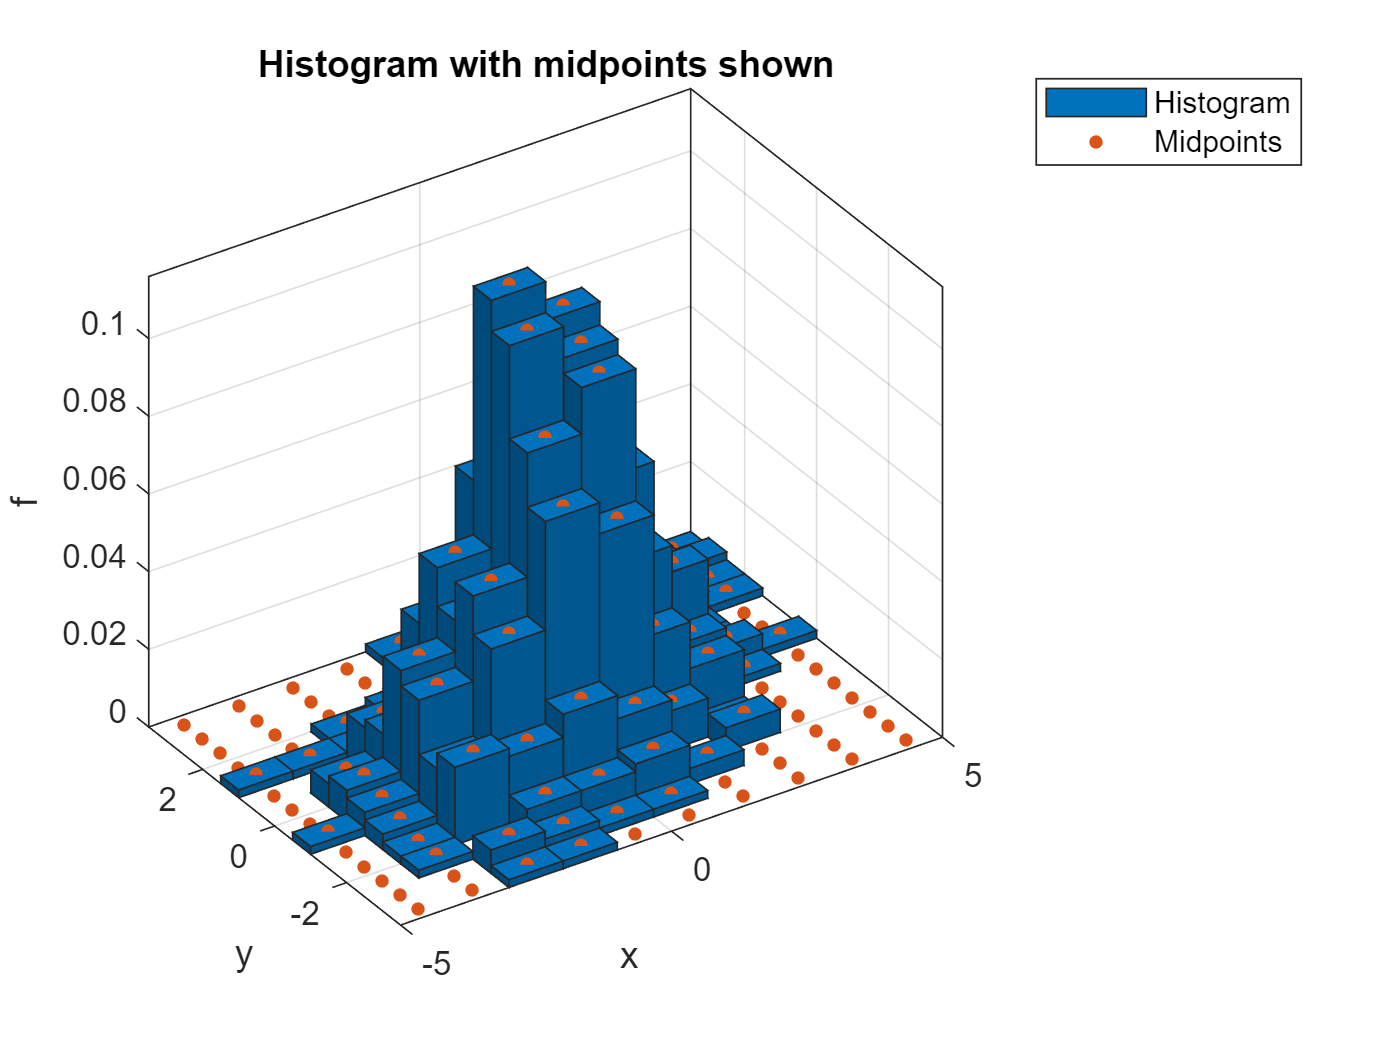

[Y, X] = meshgrid(yMidpoints, xMidpoints); % careful of the order!
xvec = X(:); yvec = Y(:); % as big columns
hold on
hp = plot3(xvec, yvec, fvec, '.', 'MarkerSize', 12, 'DisplayName', 'Midpoints');
title('Histogram with midpoints shown')

### Least Squares

Well now, we have set up a problem that is analogous to one you will tackle in Part I of the group project.  There are $N$ "measurements" (i.e.  red dots in 3D space)

N = length(fvec)

N = 140

and we want to find the matrix $K = \left[ \matrix{k_{xx} & k_{xy} \cr k_{xy} & k_{yy}  }\right]$ such that the function


$$f(\mathbf{x}) = \frac{1}{2\pi}\sqrt{\det(K)} \exp\left(-\frac{1}{2}\mathbf{x}^T K \mathbf{x}\right)$$


goes through those dots as nearly as possible.

A least squares problem if ever there was one -- but it certainly doesn't look linear!  Are we sure we can handle it?

First up, what are the unknowns.  What are we actually solving for?  Well, it's the matrix $K$, which is really just three independent numbers: $k_{xx}$, $k_{yy}$ and $k_{xy}$.

syms k_xx k_yy k_xy real
K = [k_xx k_xy ; k_xy k_yy]

$$K = \left(\begin{array}{cc} k_{\mathrm{xx}} & k_{\mathrm{xy}}\\ k_{\mathrm{xy}} & k_{\mathrm{yy}} \end{array}\right)$$

And here's the function $f$:

sympref('FloatingPointOutput',false);
syms x y real
f = 1/2/sym(pi) * sqrt(det(K)) * exp(-1/2 * [x;y]'*K*[x;y])

$$f = \frac{{\mathrm{e}}^{-x\,\left(\frac{k_{\mathrm{xx}}\,x}{2}+\frac{k_{\mathrm{xy}}\,y}{2}\right)-y\,\left(\frac{k_{\mathrm{xy}}\,x}{2}+\frac{k_{\mathrm{yy}}\,y}{2}\right)}\,\sqrt{k_{\mathrm{xx}}\,k_{\mathrm{yy}}-{k_{\mathrm{xy}}}^{2}}}{2\,\pi }$$

So... certainly not linear in $k_{xx}$, $k_{yy}$ and $k_{xy}$ then!

But don't despair, maybe we can find a trick up our sleeve.  First, let's deal with that leading coefficient $\frac{1}{2\pi}\sqrt{\det(K)}$ by just treating it as an unknown factor $C$ (*this step is not necessary in your group project).*


$$f(\mathbf{x}) = C\exp\left(-\frac{1}{2}\mathbf{x}^T K \mathbf{x}\right)$$


There, much better already.  Now we have an additional unknown $C$, to go with our unknowns  $k_{xx}$, $k_{yy}$ and $k_{xy}$.  This comes with a downside: there is no guarantee that the fitted value of $C$ will actually equal $\frac{1}{2\pi}\sqrt{\det(K)}$ anymore, but we'll live with that for the added simplicity it provides to the model.  Provided we have enough data, it should come out alright -- the model still has to fit the data after all.

Now, if we *take log*s, things will suddenly be looking much more promising (*this step is crucial for your group project)*:


$$\log(f(\mathbf{x})) = \log(C) - \frac{1}{2}\mathbf{x}^T K \mathbf{x}$$


And this *is* linear in the unknowns $\log(C),$ $k_{xx}$, $k_{yy}$ and $k_{xy}$, as we can see by expanding it all out.

syms C
logf = expand(log(C) - 1/2* [x;y]'*K*[x;y])

$$logf = -\frac{k_{\mathrm{xx}}\,x^{2}}{2}-k_{\mathrm{xy}}\,x\,y-\frac{k_{\mathrm{yy}}\,y^{2}}{2}+\log\left(C\right)$$

So we're back on familiar, linear, ground.  We can use the data we have for $f$  (which are the scaled histogram counts), $x$ and $y$ (which are the bin midpoints) to fit the unknown parameters $\log(C),$ $k_{xx}$, $k_{yy}$ and $k_{xy}$ using linear least squares.

Over to you now!  Go ahead and form the coefficient matrix $A$ and right hand side vector $b$ for the least squares problem

$\log(f_i) = \log(C) - \frac{{x_i}^2}{2}\, k_{xx} - \frac{{y_i}^2}{2}\, k_{yy} - x_i\, y_i\, k_{xy}$,     $i = 1,\ldots,\textrm{npts}$.

i = (1:N)';
A = [ones(size(i)) -xvec.^2/2 -yvec.^2/2 -xvec.*yvec];
b = log(fvec);

Once you have them, just hit it with backslash and you'll be done!

c = A \ b  % least squares solution

c =    NaN
   NaN
   NaN
   NaN


Oh dear.  Are you getting NaNs for your solution?

If so, take a close look at the entries in the right hand side vector $b$.  Do you have lots of negative infinities in there?  I certainly did!

The problem is that our model


$$\log(f(\mathbf{x})) = \log(C) - \frac{1}{2}\mathbf{x}^T K \mathbf{x}$$


blows up when $f(\mathbf{x})$ is zero.  And we have *heaps* of data points with $f(\mathbf{x}) = 0$: any bin which had no observations.

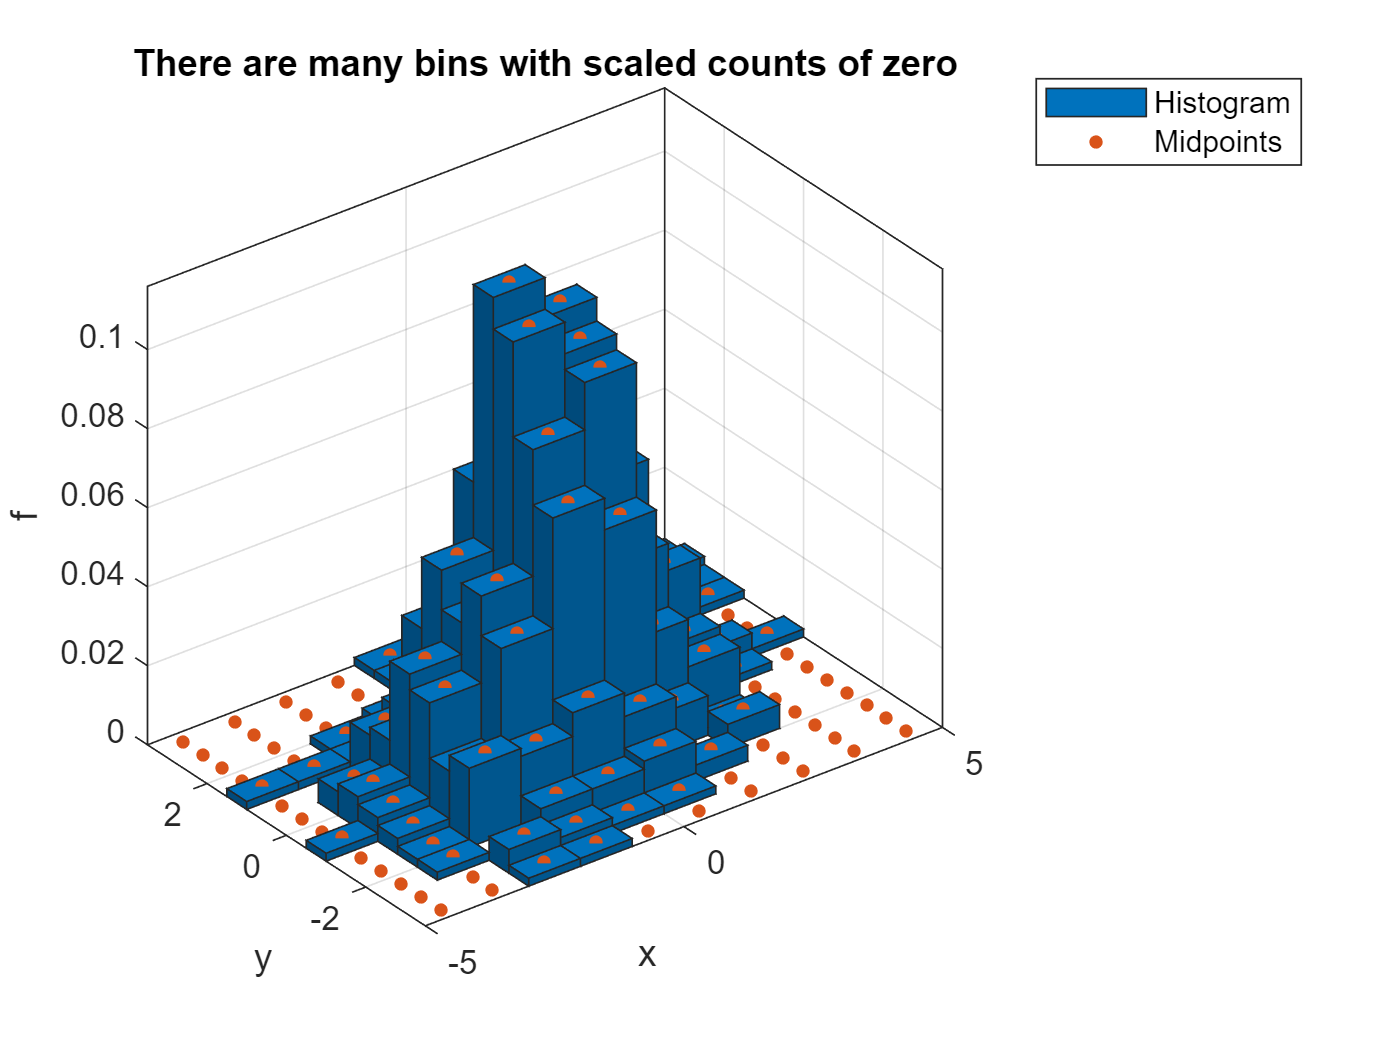

title('There are many bins with scaled counts of zero')

Well, we really should be excluding these points from our least squares fit anyway.  (*Dealing approriately with bad data is an essential part for your group project too.*)  Just because we had zero observations falling in those bins, doesn't mean we believe the probability should truly be zero there.  It's just a consequence of not having enough data to get meaningful counts in all the bins.

Actually, we should probably exclude any bins for which there were only a few counts, becuase they'll also be inaccurate.

Let's set a threshold of a bin value being at least 10% of the maximum recorded value.

We'll use the `find` command to get the *index vector* for all the values in `F` for which this is true.

idx = find(F >= 0.1*max(F(:)))  % which bins exceed the threshold?

idx =     33
    34
    35
    36
    43
    44
    45
    46
    53
    54


So this means that observations $i \in \textrm{idx}$ (so, $i = 33, 34, 35$, etc.) are all considered to be "good data".  Let's check that this accords with our figure.

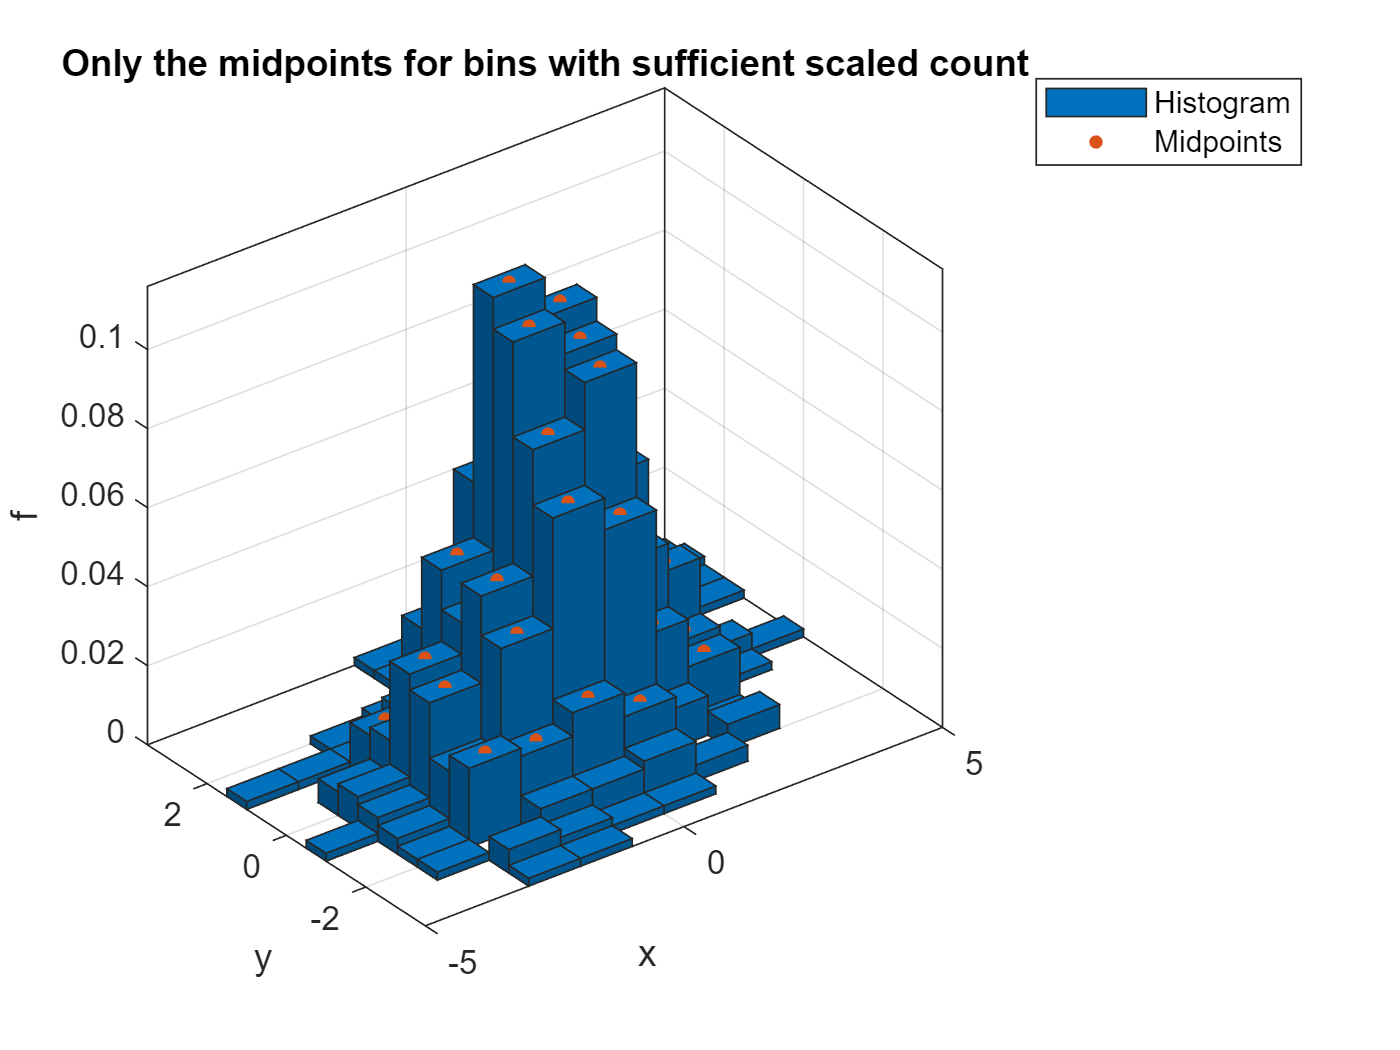

hp.XData = xvec(idx); hp.YData = yvec(idx); hp.ZData = fvec(idx);  % just plot the "good data"
title('Only the midpoints for bins with sufficient scaled count')

Right, let's try that again!  This time form the matrix $A$ and right hand side $b$ including only those data points $i \in \textrm{idx}$.

A = [ones(size(idx)) -xvec(idx).^2/2 -yvec(idx).^2/2 -xvec(idx).*yvec(idx)];
b = log(fvec(idx));

Now try your least squares fit again.

c = A \ b % least squares solution

c =    -2.2912
    0.4924
    0.8782
   -0.2344


This time it should hopefully all go well!  But remember what we've solved for here.  The entries in your vector $c$ are the unknowns $\log(C),$ $k_{xx}$, $k_{yy}$ and $k_{xy}$.  So now you can pull it apart and assemble the precision matrix $K = \left[ \matrix{k_{xx} & k_{xy} \cr k_{xy} & k_{yy}  }\right]$ and your dummy coefficient $C$.

K = [c(2) c(4); c(4) c(3)]

K =     0.4924   -0.2344
   -0.2344    0.8782


C = exp(c(1))

C = 0.1011

For reference, the value of $K$ I got was

% K = [0.4924 -0.2344; -0.2344 0.8782]  % comment this line out once you have computed K yourself

Now that you have $K$, you can perform a little validation.  Remember that the coefficient $C$ in our model is really supposed to be $C = \frac{1}{2\pi}\sqrt{\det(K)}$.  So although you've solved for $C$ independently, if the model fit is accurate, $C$ should be roughly equal to $\frac{1}{2\pi}\sqrt{\det(K)}$.  See if it is.  If so, it should give you more confidence that your working up to this point is correct.

sqrt(det(K))/2/pi

ans = 0.0978

OK, it's show time.  You've got your precision matrix $K$, so let's substitute it into the PDF and see what we get.

sympref('FloatingPointOutput',true);
f = subs(f, {k_xx, k_xy, k_yy}, {K(1,1), K(1,2), K(2,2)})

$$f = 0.0978\,{\mathrm{e}}^{y\,\left(0.1172\,x-0.4391\,y\right)-x\,\left(0.2462\,x-0.1172\,y\right)}$$

As another sanity check, this is a probability density function, so it should integrate to 1.

int(int(f, x, [-inf,inf]), y, [-inf,inf])

$$ans = 1$$

Now let's overlay our PDF with the histogram to see how good the fit is.

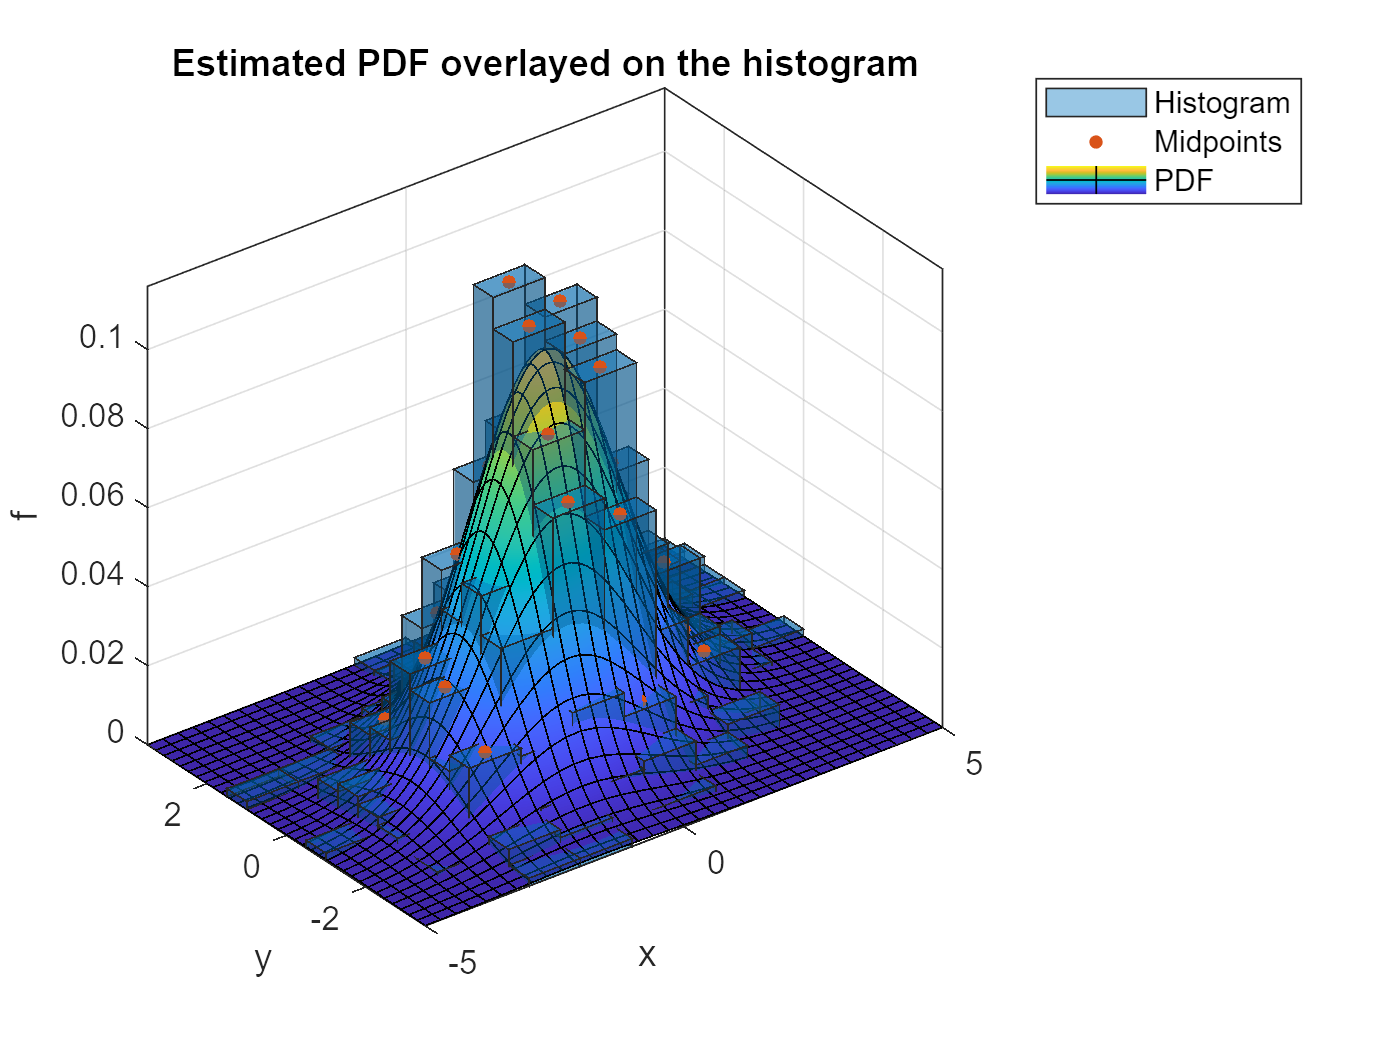

h.FaceAlpha = 0.4;
xlabel x, ylabel y, zlabel f
fsurf(f, 'DisplayName', 'PDF')
title('Estimated PDF overlayed on the histogram')

So in all honesty, the fit isn't spectacular.  There is a definite loss in accuracy from treating $C$ as an independent parameter.  The model thought it was free to vary $C$, but in fact it's supposed to be completely determined by $k_{xx}$, $k_{yy}$ and $k_{xy}$.  When we put in the true value $C = \frac{1}{2\pi}\sqrt{\det(K)}$ (which we must do so that the PDF integrates to one), we're falling a bit short.

For comparison, the actual parameters of the distribution that these data were drawn from were

mean $\mathbf{\mu} = \left[\matrix{2 \cr -1}\right]$ and covariance matrix $\Sigma = \left[ \matrix{2 & 1/2 \cr 1/2 & 1  }\right]$

whereas our estimates are

mu % quite decent

mu =     1.9812   -0.9302


and

Sigma = inv(K) % a bit meh

Sigma =     2.3264    0.6210
    0.6210    1.3044


respectively.

### The right way to do it in statistics

Side note: the *right way* to solve this problem in statistics is using *maximum likelihood estimation*.  Often this would require solving a nonlinear optimisation problem.  But for the special case of the normal distribution, everything works out beautifully, and in fact the maximum likelihood estimate of $\Sigma$ is as simple as:

Sigma = MC' * MC / npts  % this is just the sample covariance

Sigma =     1.9919    0.5148
    0.5148    1.1012


So, as already pointed out, the methodology we applied *for this particular problem* isn't optimal.  But the ideas of transforming a nonlinear model, dealing with bad data, and solving for an unknown matrix using least squares are essential tools for your group project.

## Diagonalising the matrix

So let's be happy with what we've achieved, and see what else we can learn about the data from the matrix $\Sigma$.

Since $\Sigma$ is a symmetric matrix, it has an orthogonal diagonalisation.  As usual, this diagonalisation tells us how $\Sigma$ distorts the unit circle when it acts as a linear operator.  The eigenvalues of $\Sigma$ are the lengths of the semimajor and semiminor axes, and the eigenvectors give the directions.

Let's find its diagonalisation.

[V,D] = eig(Sigma)

V =     0.4158   -0.9095
   -0.9095   -0.4158


D =     0.8658         0
         0    2.2273


lambda = diag(D)

lambda =     0.8658
    2.2273


Returning to our data, it's clear that there is a definite orientation to it, which isn't aligned with the $x$-$y$ axes.

Intuitively, the only matrix involved in the normal PDF is $\Sigma$, so the orientation information *has* to be coming from there.  And sure enough, if we overlay the eigenvector directions on our scatter plot, what do we find:

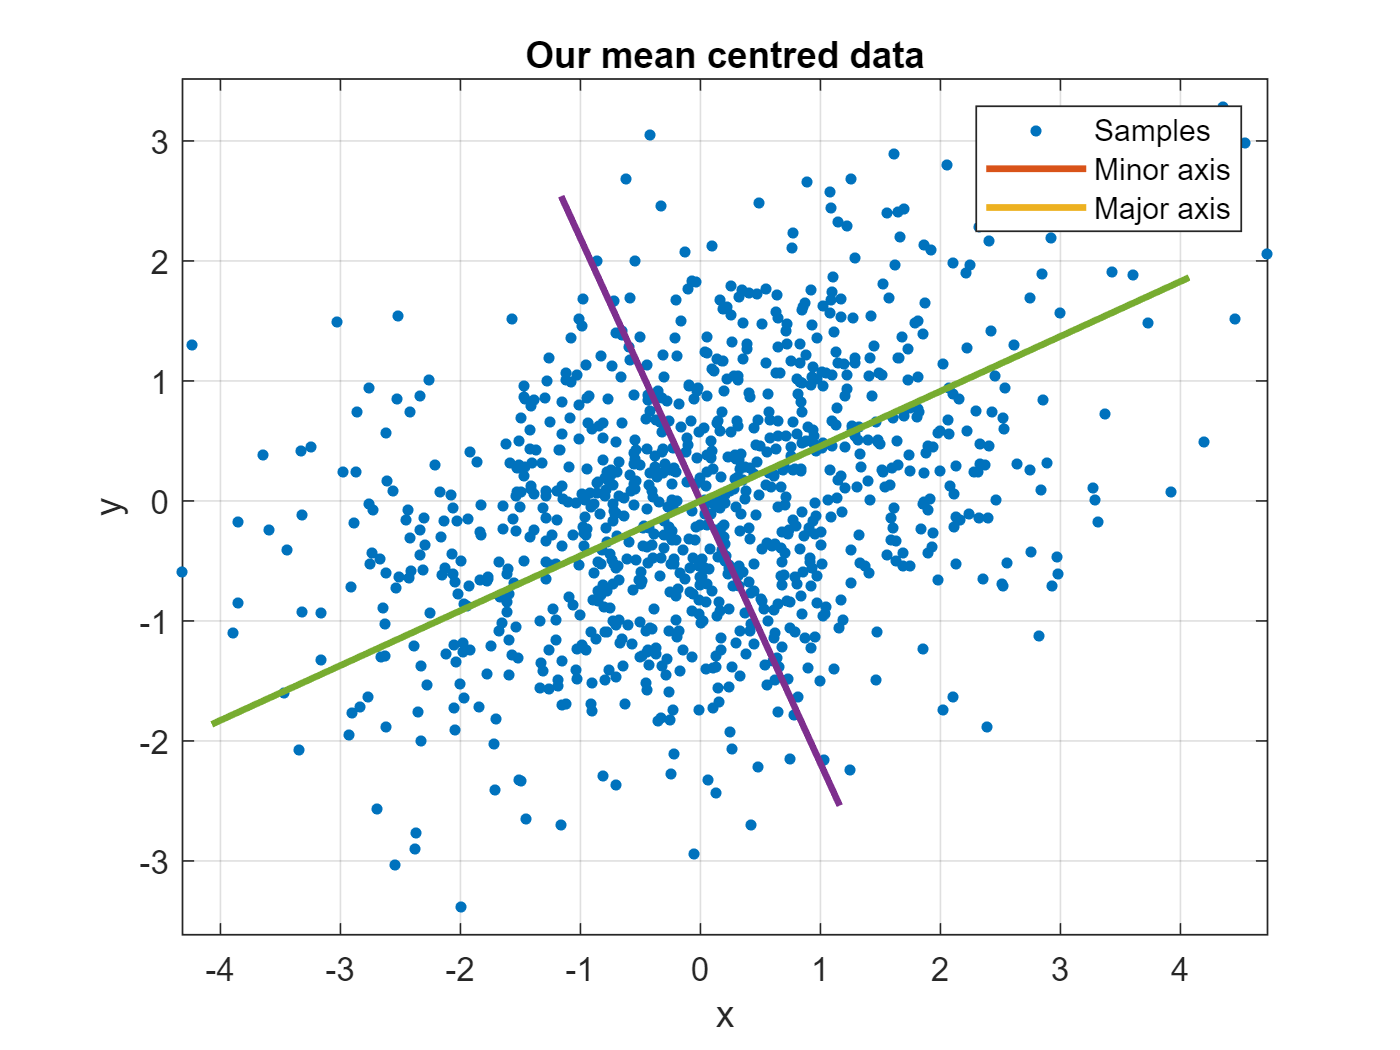

figure(f2)
v1 = V(:,1) * 3*sqrt(lambda(1)); % scaled eigenvector 1
v2 = V(:,2) * 3*sqrt(lambda(2)); % scaled eigenvector 2
hold on
plot([-v1(1) v1(1)], [-v1(2) v1(2)], 'LineWidth', 2)
plot([-v2(1) v2(1)], [-v2(2) v2(2)], 'LineWidth', 2)
legend('Samples', 'Minor axis', 'Major axis')

If you notice, in the code we're using 3 times the square roots of the respective eigenvalues as the semiaxis lengths.  The eigenvalues evidently play the role of *variance *in the two principal directions.  The factor of $3\sqrt{\lambda}$ is just the old rule of thumb that "~99% of the data lie within 3 *standard deviations* of the mean".

## Wrap-up

So that's the normal distribution in 2D nicely wrapped up then.  I suppose there is one final loose end, which is to undo the mean centring we applied right at the start, and generate the true PDF for the uncentred data.  It's nothing but a translation by the mean, so to spice it up slightly, why don't you also plot the ellipse corresponding to 3 standard deviations from the mean.  You can also check how well the data follow the 99% rule.

f3 = figure;

plot(R(:,1), R(:,2), '.', 'MarkerSize', 10)
hold on

xlabel x
ylabel y
axis equal

plot([-v1(1)+mu(1) v1(1)+mu(1)], [-v1(2)+mu(2) v1(2)+mu(2)], 'LineWidth', 2)
plot([-v2(1)+mu(1) v2(1)+mu(1)], [-v2(2)+mu(2) v2(2)+mu(2)], 'LineWidth', 2)

mag1 = norm(v1);
mag2 = norm(v2);

ang = atan(v1(2)/v1(1));
ellipse = @(x, y) ( (x - mu(1))*cos(ang) + (y - mu(2))*sin(ang) )^2 / mag1^2 + ( (x - mu(1))*sin(ang) - (y - mu(2))*cos(ang) )^2 / mag2^2 - 1

ellipse = function_handle with value:
    @(x,y)((x-mu(1))*cos(ang)+(y-mu(2))*sin(ang))^2/mag1^2+((x-mu(1))*sin(ang)-(y-mu(2))*cos(ang))^2/mag2^2-1


fimplicit(ellipse, 'LineWidth', 2)

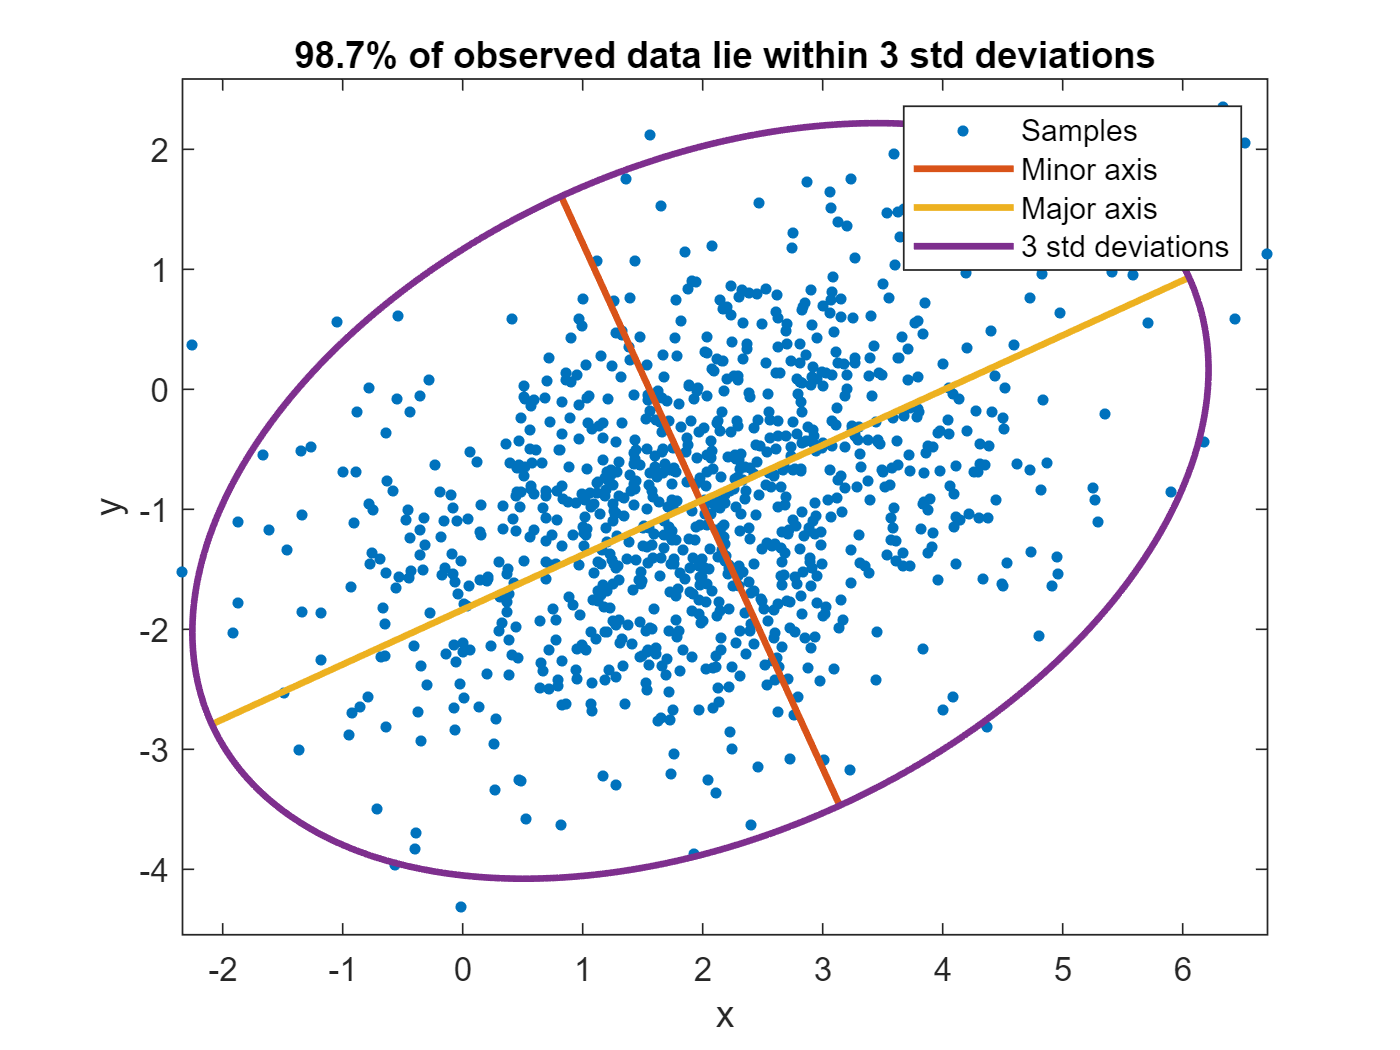


legend('Samples', 'Minor axis', 'Major axis', '3 std deviations')
title("98.7% of observed data lie within 3 std deviations")

hold off